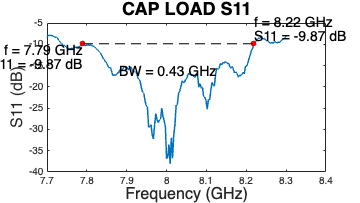

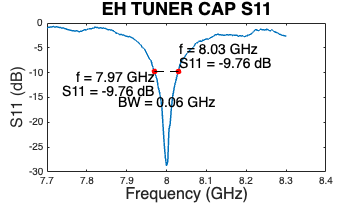

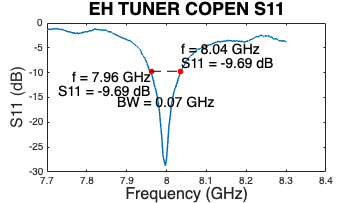

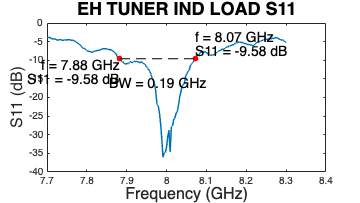

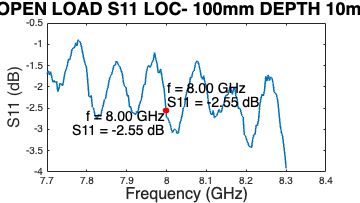

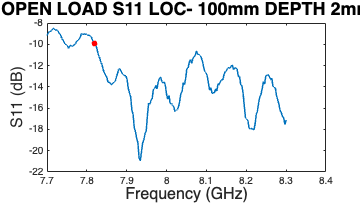

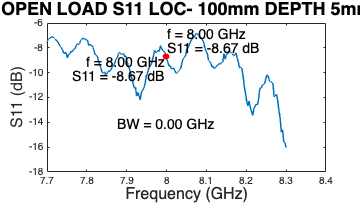

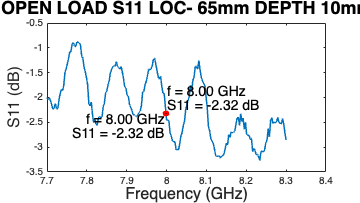

% Prompt user to input path to directory containing CSV files
dir_path = input('Enter path to directory containing CSV files: ', 's');
s11_val = input('Enter the S11 value (in dB) at which to mark the points: ');

% Get a list of all the CSV files in the directory
csv_files = dir(fullfile(dir_path, '*.csv'));

% Loop over each CSV file and generate a plot
for i = 1:numel(csv_files)
    % Load CSV file and extract frequency and S11 data
    csv_path = fullfile(csv_files(i).folder, csv_files(i).name);
    [~, file_name, ~] = fileparts(csv_path);
    plot_title = strrep(file_name, '_', ' '); % replace underscores with spaces
    data = readmatrix(csv_path);
    freq = data(:, 1)/1e9; % convert frequency to GHz
    s11 = data(:, 2);
    
    % Find the indices of the frequencies where the value of S11 is -10 dB
    idx1 = find(s11 >= s11_val & freq < 8, 1, 'last');
    idx2 = find(s11 >= s11_val & freq >= 8, 1, 'first');
    

    
    % Calculate the mean of S11 at the two points
    mean_s11 = mean([s11(idx1), s11(idx2)]);
    
    % Calculate the frequency delta between the two points
    delta_freq = abs(freq(idx1) - freq(idx2));
    
    % Plot the S11 data in linear scale
    figure('Units', 'normalized', 'Position', [0.2, 0.2, 0.6, 0.6]);
    plot(freq, s11, 'LineWidth', 1.5);
    xlabel('Frequency (GHz)', 'FontSize', 16);
    ylabel('S11 (dB)', 'FontSize', 16);
    title(plot_title, 'FontSize', 18);
    hold on;
    
    % Mark the points where S11 is -10 dB with red circles
    scatter(freq(idx1), mean_s11, 'ro', 'filled');
    scatter(freq(idx2), mean_s11, 'ro', 'filled');
    
    % Draw a line between the two points with -- style
    plot([freq(idx1), freq(idx2)], [mean_s11, mean_s11], '--', 'Color', 'k');


    if isempty(idx1) || isempty(idx2)
        % The two points were not found, so skip to the next file
        hold off;
        % Save the plot as a PNG file in the same directory as the CSV file
        png_path = fullfile(dir_path, sprintf('%s.png', file_name));
        saveas(gcf, png_path);
        continue;
    end
    % Display the delta frequency as text in the plot
    text((freq(idx1)+freq(idx2))/2, mean_s11-5, sprintf('BW = %.2f GHz', delta_freq), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', 'FontSize', 14);
    % Display the frequency and S11 value where S11 is -10 dB in the plot
    text(freq(idx1), mean_s11, sprintf('f = %.2f GHz\nS11 = %.2f dB', freq(idx1), mean_s11), 'HorizontalAlignment', 'right', 'VerticalAlignment', 'top', 'FontSize', 14);
    text(freq(idx2), mean_s11, sprintf('f = %.2f GHz\nS11 = %.2f dB', freq(idx2), mean_s11), 'HorizontalAlignment', 'left', 'VerticalAlignment', 'bottom', 'FontSize', 14);
    % Check if the indices are valid
    hold off;
    png_path = fullfile(dir_path, sprintf('%s.png', file_name));
    saveas(gcf, png_path)
end